## PART 1: KINEMATICS

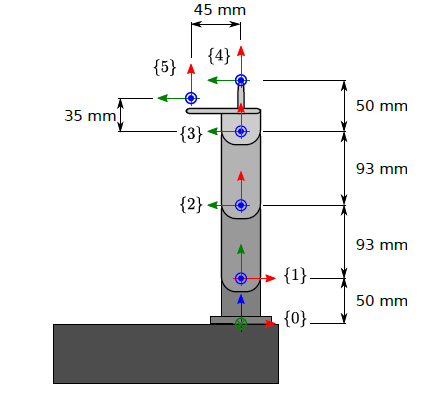

### Problem 1:

Find, by the use of Figure 1, the direct kinematic transformations, $$T_{4}^{0}$$ for the robot stylus, and $$T_{5}^{0}$$ for the robot camera, as function of all joint angles.

% Preliminary transformations

L01 = 50;
L12 = 93;
L23 = 93;
L34 = 50;
L45 = 45;
L35 = 35;

% % Uncomment for symbolic representation
syms theta0 theta1 theta2 theta3 

% Rotation matrices
R_x_90 = [1 0 0 0;
          0 0 -1 0;
          0 1 0 0;
          0 0 0 1];
R_z_90 = [0 -1 0 0;
          1 0 0 0;
          0 0 1 0;
          0 0 0 1];
R_z_th0 = [cos(theta0) -sin(theta0) 0 0;
       sin(theta0) cos(theta0) 0 0;
       0 0 1 0;
       0 0 0 1];
R_z_th1 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];
R_z_th2 = [cos(theta2) -sin(theta2) 0 0;
       sin(theta2) cos(theta2) 0 0;
       0 0 1 0;
       0 0 0 1];
R_z_th3 = [cos(theta3) -sin(theta3) 0 0;
       sin(theta3) cos(theta3) 0 0;
       0 0 1 0;
       0 0 0 1];
% Translation matrices
t01 = [1 0 0 0;
       0 1 0 0;
       0 0 1 L01;
       0 0 0 1];
t12 = [1 0 0 L12;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
t23 = [1 0 0 L23;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
t34 = [1 0 0 L34;
       0 1 0 0;
       0 0 1 0;
       0 0 0 1];
t35 = [1 0 0 L35;
       0 1 0 L45;
       0 0 1 0;
       0 0 0 1];

% {0} -> {1}
T01 = R_x_90*R_z_th0*t01;

% {1} -> {2}
T12 = R_z_90*R_z_th1*t12;

% {2} -> {3}
T23 = R_z_th2*t23;

% {3} -> {4}
T34 = R_z_th3*t34;

% {3} -> {5}
T35 = R_z_th3*t35;

% Transformation from {0} to {4}
T04 = T01*T12*T23*T34

$$T04 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & \sin\left(\theta_{3}\right)\,\sigma_{3}-\cos\left(\theta_{3}\right)\,\sigma_{2} & 0 & -93\,\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)-93\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)-50\,\cos\left(\theta_{3}\right)\,\sigma_{3}-50\,\sin\left(\theta_{3}\right)\,\sigma_{2}-93\,\cos\left(\theta_{2}\right)\,\sigma_{5}-93\,\sin\left(\theta_{2}\right)\,\sigma_{4}\\ 0 & 0 & -1 & -50\\ \cos\left(\theta_{3}\right)\,\sigma_{2}-\sin\left(\theta_{3}\right)\,\sigma_{3} & \sigma_{1} & 0 & 93\,\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-93\,\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+50\,\cos\left(\theta_{3}\right)\,\sigma_{2}-50\,\sin\left(\theta_{3}\right)\,\sigma_{3}+93\,\cos\left(\theta_{2}\right)\,\sigma_{4}-93\,\sin\left(\theta_{2}\right)\,\sigma_{5}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\cos\left(\theta_{3}\right)\,\sigma_{3}-\sin\left(\theta_{3}\right)\,\sigma_{2}\\ \sigma_{2}=\cos\left(\theta_{2}\right)\,\sigma_{4}-\sin\left(\theta_{2}\right)\,\sigma_{5}\\ \sigma_{3}=\cos\left(\theta_{2}\right)\,\sigma_{5}+\sin\left(\theta_{2}\right)\,\sigma_{4}\\ \sigma_{4}=\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{5}=\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right) \end{array}$$


% Transformation from {0} to {5}
T05 = T01*T12*T23*T35

$$T05 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3} & \sin\left(\theta_{3}\right)\,\sigma_{5}-\cos\left(\theta_{3}\right)\,\sigma_{4} & 0 & -93\,\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)-93\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right)-\sigma_{5}\,\sigma_{1}-\sigma_{4}\,\sigma_{2}-93\,\cos\left(\theta_{2}\right)\,\sigma_{7}-93\,\sin\left(\theta_{2}\right)\,\sigma_{6}\\ 0 & 0 & -1 & -50\\ \cos\left(\theta_{3}\right)\,\sigma_{4}-\sin\left(\theta_{3}\right)\,\sigma_{5} & \sigma_{3} & 0 & 93\,\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-93\,\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)-\sigma_{5}\,\sigma_{2}+\sigma_{4}\,\sigma_{1}+93\,\cos\left(\theta_{2}\right)\,\sigma_{6}-93\,\sin\left(\theta_{2}\right)\,\sigma_{7}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=35\,\cos\left(\theta_{3}\right)-45\,\sin\left(\theta_{3}\right)\\ \sigma_{2}=45\,\cos\left(\theta_{3}\right)+35\,\sin\left(\theta_{3}\right)\\ \sigma_{3}=-\cos\left(\theta_{3}\right)\,\sigma_{5}-\sin\left(\theta_{3}\right)\,\sigma_{4}\\ \sigma_{4}=\cos\left(\theta_{2}\right)\,\sigma_{6}-\sin\left(\theta_{2}\right)\,\sigma_{7}\\ \sigma_{5}=\cos\left(\theta_{2}\right)\,\sigma_{7}+\sin\left(\theta_{2}\right)\,\sigma_{6}\\ \sigma_{6}=\cos\left(\theta_{0}\right)\,\cos\left(\theta_{1}\right)-\sin\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{7}=\cos\left(\theta_{0}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\sin\left(\theta_{0}\right) \end{array}$$

### Problem 2: 

Determine the inverse kinematic transformation


$$$q = [q_1, q_2, q_3, q_4]^T = f(x_{4}^0, o_{4}^0)$$$


where $$x_{4}^{0}$$ are the first 3 components of the first column of $$T_{4}^{0}$$ , and $$o_{4}^{0}$$ are the first 3 components of the last column of $$T_{4}^{0}$$ , respectively. Satisfy all position components in $$o_{4}^{0}$$ and as many components in $$x_{4}^{0}$$ as possible.

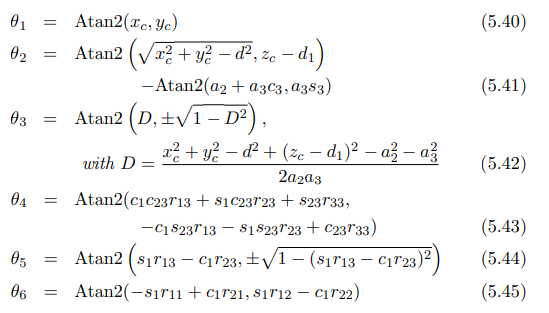

xc = 100;
yc = 100;
zc = 100;


d = L12; % or 23
D = (xc^2 + yc^2 - d^2 + (zc - L01)^2 - L12^2 - L23^2)/(2*L12*L23)

D = -0.1993


% create r

R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;



t0 = atan2(xc,yc);

t2 = atan2(D, sqrt(1-D^2));

t1 = atan2(sqrt(xc^2 + yc^2 - d^2) , zc - L01) - atan2(L12+L23*cos(t3), L23*sin(t3));

Unrecognized function or variable 't3'.


R01 = [1 0 0 0;
       0 cos(theta0) -sin(theta0) 0;
       0 sin(theta0) cos(theta0) 0;
       0 0 0 1];
% {1} -> {2}
R12 = [cos(theta1) -sin(theta1) 0 0;
       sin(theta1) cos(theta1) 0 0;
       0 0 1 0;
       0 0 0 1];

R = R01*R12;





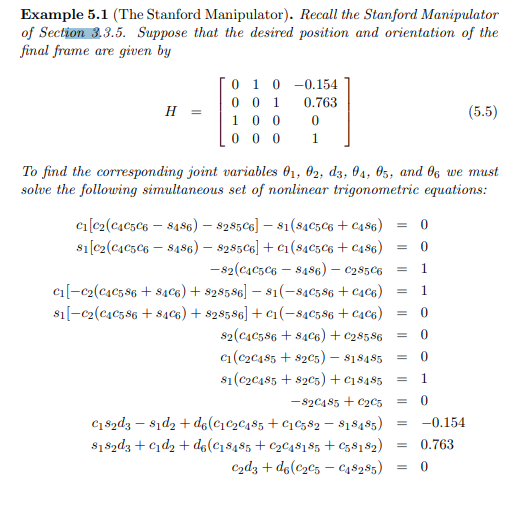

Next up we need to set up and solve this mess of equations.

We have the equations for T04 in the original matrixes calculated from the symbolic variables and we can derive the absolute value of H from the theta values calculated from the grapically derived equations.

## **Problem 3:**

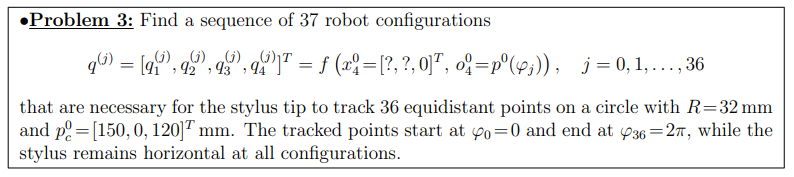


% origin of the circle to be traced
xc = 150;
yc = 100;
zc = 100;

angles = 0:2*pi/36:2*pi % this is the phi angle reported in the previous line


dy = cos(angles)*16;
dz = sin(angles)*16;

x = zeros(1,length(angles))
y = yc + dy
z = zc + dz

[t1,t2,t3] = theta(x,y,z)

t4 = ones(1,length(x)).*(pi-t1-t2-t3) % ensures horizontality

% R01 = [1 0 0 0;
%        0 cos(t1) -sin(t1) 0;
%        0 sin(t1) cos(t1) 0;
%        0 0 0 1];
% % {1} -> {2}
% R12 = [cos(t2) -sin(t2) 0 0;
%        sin(t2) cos(t2) 0 0;
%        0 0 1 0;
%        0 0 0 1];
% 
% R = R01*R12;
% 
% 
% t4 =atan2(cos(t1).*cos(t2+t3).*R(1,3) + sin(t1).*cos(t2+t3).*R(2,3) + sin(t2+t3).*R(3,3), -cos(t1).*sin(t2+t3).*R(1,3) - sin(t1).*sin(t2+t3).*R(2,3)+cos(t2+t3).*R(3,3));


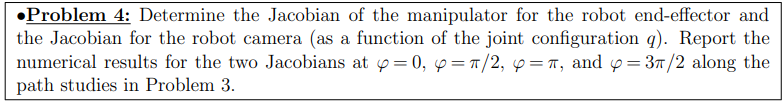

% if you need help figuring out the angles contact Palli
clc
disp("helloo")
%phi = [0 pi/2 pi 3*pi/2];
phi = pi;
dy = cos(phi)*16;
dz = sin(phi)*16;

x = zeros(1,length(phi));
y = yc + dy;
z = zc + dz;

[t1,t2,t3] = theta(x,y,z);
t4 = ones(1,length(x)).*(pi-t1-t2-t3);

for i = 1:1%length(t1)
    [T01, T12, T23, T34, T35] = T_finder(t1(i),t2(i),t3(i),t4(i));
    J = Jacob(T01, T12, T23, T34)
end